clear 
close all

omega = 2;
T = 1000;
beta = linspace(1e-4,1e-2,T);
alpha = zeros(1,T);
alpha(1) = beta(1);
for i=2:T
    alpha(i) = alpha(i-1)*beta(i);
end

temp = 0;
for t = 2:T
    temp = temp+ ((beta(t)*sqrt(alpha(t-1))+sqrt(1-beta(t))*(1-alpha(t-1))*sqrt(alpha(t))))^2/(1-alpha(t))./...
        (1-beta(t))./(1-alpha(t-1))^2;
end

tauA = @(a) a*omega^2/2*temp;
% (order,tau) Curve for the RDP
order = [1.1:0.1:10,11:20]

order =     1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000    6.0000


tau = tauA(order)

tau = 1.0e-06 *

    0.0247    0.0269    0.0292    0.0314    0.0337    0.0359    0.0382    0.0404    0.0427    0.0449    0.0471    0.0494    0.0516    0.0539    0.0561    0.0584    0.0606    0.0629    0.0651    0.0673    0.0696    0.0718    0.0741    0.0763    0.0786    0.0808    0.0831    0.0853    0.0875    0.0898    0.0920    0.0943    0.0965    0.0988    0.1010    0.1033    0.1055    0.1078    0.1100    0.1122    0.1145    0.1167    0.1190    0.1212    0.1235    0.1257    0.1280    0.1302    0.1324    0.1347



zeta = 1./order.*(1-1./order).^(order-1)

zeta =     0.7153    0.5824    0.4955    0.4328    0.3849    0.3470    0.3161    0.2904    0.2686    0.2500    0.2338    0.2196    0.2071    0.1959    0.1859    0.1769    0.1687    0.1612    0.1544    0.1481    0.1424    0.1370    0.1321    0.1275    0.1232    0.1192    0.1154    0.1119    0.1086    0.1055    0.1025    0.0997    0.0971    0.0946    0.0922    0.0900    0.0878    0.0857    0.0838    0.0819    0.0801    0.0784    0.0768    0.0752    0.0737    0.0722    0.0709    0.0695    0.0682    0.0670


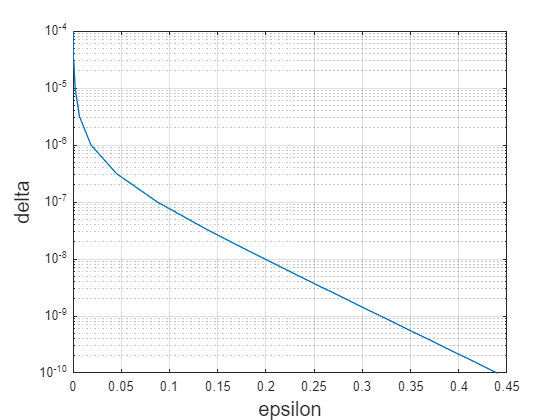

delta = 10.^(-10:0.5:-4);
eps = zeros(size(delta));
for i=1:length(delta)
    if order*delta(i)>=1
        eps(i) = min(max(tau+log(1-delta(i)),0));
    end
    if order*delta(i)>0
        eps(i) = min(1./(order-1).*min(max(0,(order-1).*tau-log(delta(i)./zeta)),log((exp(tau.*(order-1))-1)./order./delta(i)+1)));
    else
        eps(i) = 0;
        disp("Error!")
    end
end
semilogy(eps,delta)
xlabel("epsilon",FontSize=15)
ylabel("delta",FontSize=15)
grid on